# Border Closure Model

ModSim project: modeling the effects of a border closure.

## Setup

clear; clc; close all;

## Parameters

nCountries = 4;
nPer = 100;
N = nCountries * nPer;

p_in  = 0.1;   % connection of people within countries
p_out = 0.005; % connection of people between countries
infection_rate = 0.05;
recovery_rate  = 0.1;
T = 200;          
nTrials = 500;   
delays = [0:1:20, Inf];   % inf is never close borders

## Simulation

% label each person with their country 
country = zeros(N, 1);
for c = 1:nCountries
    country((c-1)*nPer + 1 : c*nPer) = c;
end

% build the friendship map
M = zeros(N, N);
for i = 1:N
    for j = i+1:N
        if country(i) == country(j)
            p = p_in;
        else
            p = p_out;
        end
        if rand < p
            M(i,j) = 1;
            M(j,i) = 1;
        end
    end
end

Iv0 = zeros(N, 1);

Iv0(1) = 1;


results = zeros(length(delays), nTrials);
for d = 1:length(delays)
    for k = 1:nTrials
        [Sh, Ih, Rh, tDetect] = simulate_absir(M, Iv0, T, infection_rate, recovery_rate, country, delays(d));
        results(d, k) = sum(Rh(:, end));
    end
end

avg = mean(results, 2);
ratio = avg / avg(end);

% find the longest delay that cuts deaths in half
threshold = -1;
for d = 1:length(delays)-1
    if ratio(d) <= 0.5
        threshold = delays(d);
    end
end
disp(threshold)

     1



## Results

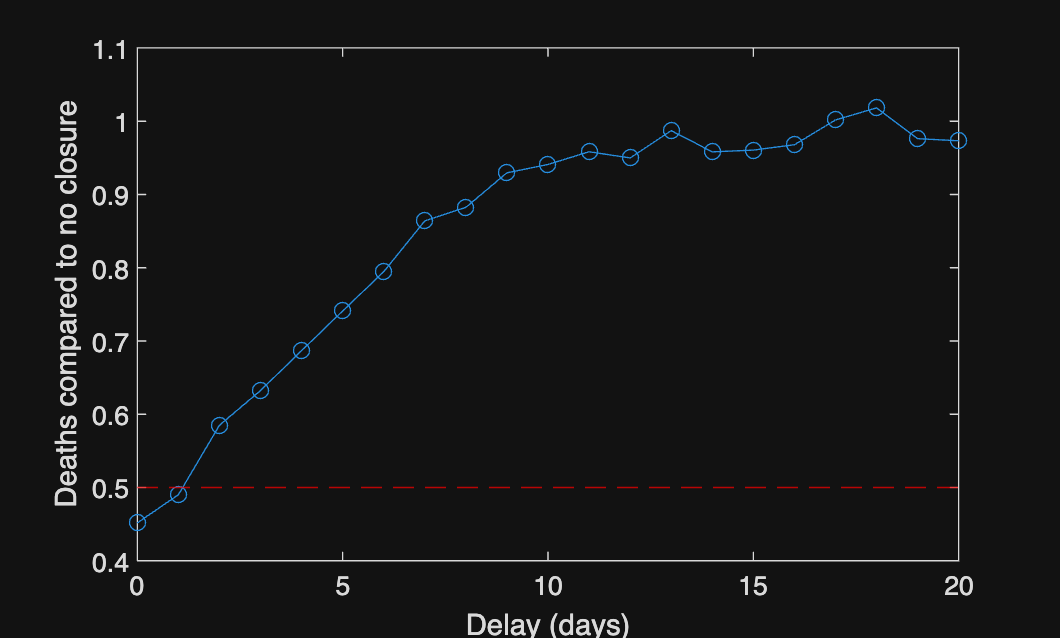

figure
plot(delays(1:end-1), ratio(1:end-1), '-o')
hold on
yline(0.5, '--r')
xlabel('Delay (days)')
ylabel('Deaths compared to no closure')